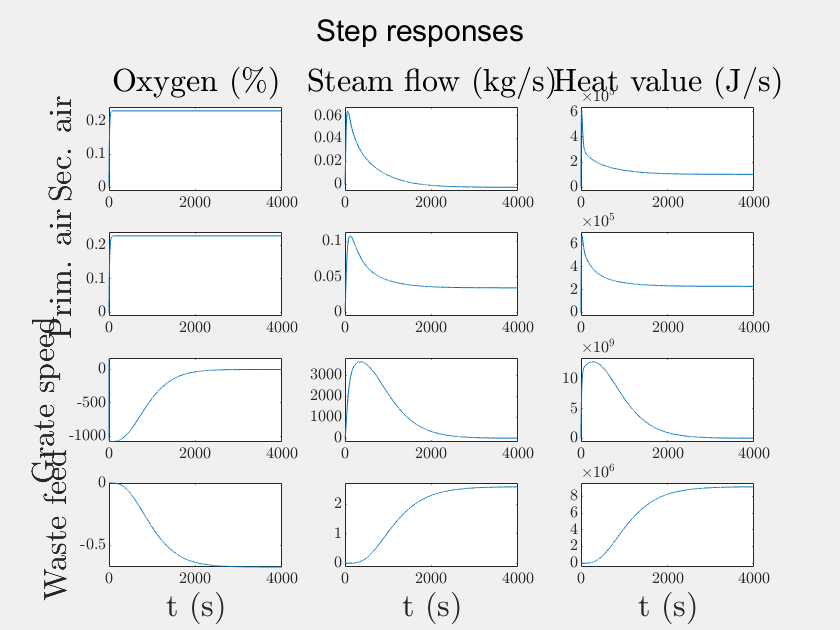

$F_{aII}$ & $F_{O2}$ & 421 ms & 25.3 s \\

$F_{aII}$ & $F_{st}$ & 5.33 s & 38.4 s \\

$F_{aII}$ & $HHV$ & 24.8 ms & 8.65 s \\

$F_{aI}$ & $F_{O2}$ & 687 ms & 31.9 s \\

$F_{aI}$ & $F_{st}$ & 8.34 s & 1.13 min \\

$F_{aI}$ & $HHV$ & 33.4 ms & 13.5 s \\

$v_{grate}$ & $F_{O2}$ & 1.74 ms & 1.16 s \\

$v_{grate}$ & $F_{st}$ & 16.9 s & 2.93 min \\

$v_{grate}$ & $HHV$ & 4.71 ms & 56.5 s \\

$F_w$ & $F_{O2}$ & 7.65 min & 29.2 min \\

$F_w$ & $F_{st}$ & 9.36 min & 34.3 min \\

$F_w$ & $HHV$ & 8.42 min & 33.2 min \\

% Create and plot the step responses of the Furnace model. Also compare
% this with the linearized system step responses. This live script assumes
% the following variables are defined in the workspace.
%
%   linsys:     ss (State-space model) used for the internal model. Acquire
%               this by doing
%                   >> linsys = linearize_model(12000);
%   ss_state:   ModelOperatingPoint representing a steady state of the
%               system. Do
%                   >> ss_state = create_ss_state(12000);
%               to create it from scratch.

clf;
warning('off','all');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
FurnaceParameters;


%%% Begin configuration %%%

run_time = 4000;        % Simulation run time in seconds.
reset_all = false;       % Set to true if you want to resimulate step responses
                        % instead of loading from workspace.
                        
%%% End configuration %%%

mvs = ["F_aII", "F_aI", "v_grate", "F_w_in"];
mv_names = ["Sec. air", "Prim. air", "Grate speed", "Waste feed"];
cv_names = ["Oxygen (\%)", "Steam flow (kg/s)", "Heat value (J/s)"];

if reset_all
    yss = {};   % Responses
    tyss = {};  % Response times
    dus = [];   % MV step size
    
    % Get MV step sizes
    for n = 1:length(mvs)
        mv = mvs(n);
        dus(n) = eval(sprintf("reg.const_%s * 0.1", mv));
    end
    
    for n = 1:length(mvs)
        mv = mvs(n);    % MV name
        du = dus(n);    % Step size
        
        % Reset parameters and set all input types to constant.
        FurnaceParameters; 
        suffixes = ["F_aI" "F_aII" "F_w_in" "v_grate" "HHV" "AB"];
        for i = 1:length(suffixes)
            evalin('caller',...
                sprintf("reg.input_type_%s = InputType.Constant;", suffixes(i)));
        end
        % Apply MV step
        eval(sprintf("reg.const_%s = reg.const_%s + %.8e", mv, mv, du));
        
        % Do simulation
        ss_time = ss_state.snapshotTime;
        stop_time = ss_time + run_time;
        set_param(...
            'Furnace',...
            'LoadInitialState', 'on',...
            'InitialState', 'ss_state'...
        );
        
        curSim = sim(...
            'Furnace',...
            'StartTime', sprintf('%d', ss_time),...
            'StopTime', sprintf('%d', stop_time)...
        );
    
        % Load response data
        ys = {};
        tys = {};
        [ys{1}, tys{1}, ~, ~] = load_data('O2', curSim);
        [ys{2}, tys{2}, ~, ~] = load_data('st', curSim);
        [ys{3}, tys{3}, ~, ~] = load_data('HHV', curSim);
        
        % Save to workspace
        yss{n} = ys;
        tyss{n} = tys;
    end
    
    % Get the linear system responses
    yss_lin = {};
    tyss_lin = {};
    
    tys_lin = 0:1:run_time;
    us_op_lin = repmat([0 0 0 0], length(tys_lin), 1);
    for i = 1:4
        display(i);
        du = dus(i);
        
        us_lin = us_op_lin(:,:);
        us_lin(:,i) = us_lin(:,i) + du;
        
        [ys_lin, tys_lin, ~] = lsim(linsys, us_lin, tys_lin);
        yss_lin{i} = ys_lin;
        tyss_lin{i} = tys_lin;
    end
end

% Plot the model responses
figure();
set(gcf, 'Visible', 'On');

sgtitle("Step responses");
for i = 1:4
    du = dus(i);
    ys = yss{i};
    tys = tyss{i};
    for j = 1:3
        y = ys{j};
        ty = tys{j};
        dty = ty - ty(1);
        
        subplot(4,3,(i-1)*3 + j);
        rel_y = (y-y(1)) / du;
        plot(dty, rel_y);
        ylim([min(rel_y)-0.05*max(rel_y), max(rel_y)+0.05*max(rel_y)]);
        if j == 1
            ylabel(mv_names(i), 'Interpreter', 'Latex', 'FontSize', 16);
        end
        if i == 1
            title(cv_names(j), 'Interpreter', 'Latex', 'FontSize', 16);
        elseif i == 4
            xlabel("t (s)", 'Interpreter', 'Latex', 'FontSize', 16);
        end
        
        % Calculate 10% reaction and 90% rise time, and print in
        % Latex table format.
        rel_y_max = max(abs(rel_y));
        t10 = dty(find(abs(rel_y) >= rel_y_max*0.1, 1))*1000;
        if t10 >= 60000
            t10 = sprintf("%.3g min", t10/60000);
        elseif t10 >= 1000
            t10 = sprintf("%.3g s", t10/1000);
        else
            t10 = sprintf("%.3g ms", t10);
        end
        t90 = dty(find(abs(rel_y) >= rel_y_max*0.9, 1))*1000;
        if t90 >= 60000
            t90 = sprintf("%.3g min", t90/60000);
        elseif t90 >= 1000
            t90 = sprintf("%.3g s", t90/1000);
        else
            t90 = sprintf("%.3g ms", t90);
        end
        mv_vars = ["F_{aII}" "F_{aI}" "v_{grate}" "F_w"];
        cv_vars = ["F_{O2}" "F_{st}" "HHV"];
        fprintf("$%s$ & $%s$ & %s & %s \\\\", mv_vars(i), cv_vars(j), t10, t90);
    end
end

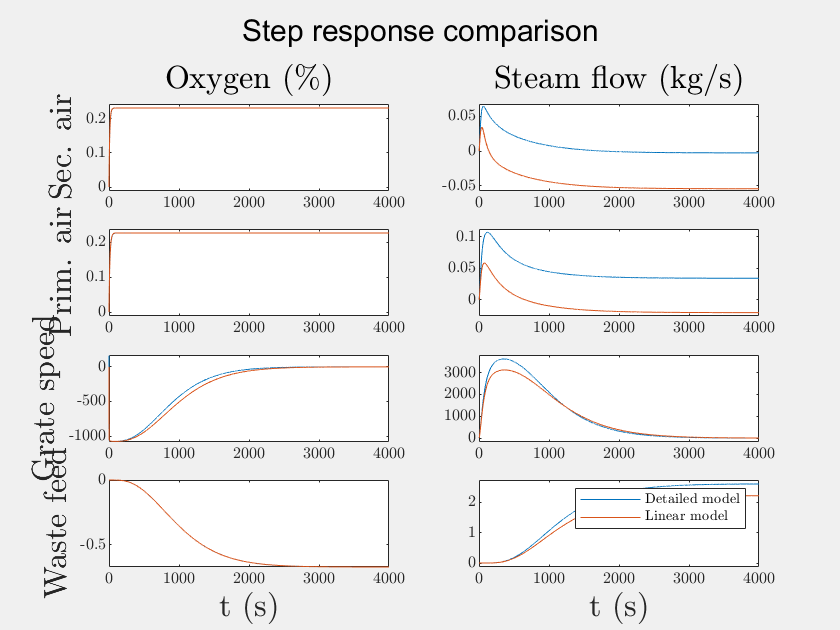


 
% Plot the comparison
figure();
set(gcf, 'Visible', 'On');

sgtitle("Step response comparison");
for i = 1:4
    du = dus(i);
    ys = yss{i};
    tys = tyss{i};
    ys_lin = yss_lin{i};
    tys_lin = tyss_lin{i};
    
    for j = 1:2
        y = ys{j};
        ty = tys{j};
        dty = ty - ty(1);
        
        y_lin = ys_lin(:,j);
        ty_lin = tys_lin;
        dty_lin = ty_lin - ty_lin(1);

        subplot(4,2,(i-1)*2 + j);
        rel_y = (y-y(1)) / du;
        rel_y_lin = (y_lin-y_lin(1)) / du;
        plot(dty, rel_y);
        hold on;
        plot(dty_lin, rel_y_lin);
        hold off;
        ymin = min([rel_y; rel_y_lin]);
        ymax = max([rel_y; rel_y_lin]);
        
        ylim([ymin-0.05*ymax, ymax+0.05*ymax]);
        if j == 1
            ylabel(mv_names(i), 'Interpreter', 'Latex', 'FontSize', 16);
        end
        if i == 1
            title(cv_names(j), 'Interpreter', 'Latex', 'FontSize', 16);
        elseif i == 4
            xlabel("t (s)", 'Interpreter', 'Latex', 'FontSize', 16);
        end
    end
end
legend('Detailed model', 'Linear model');